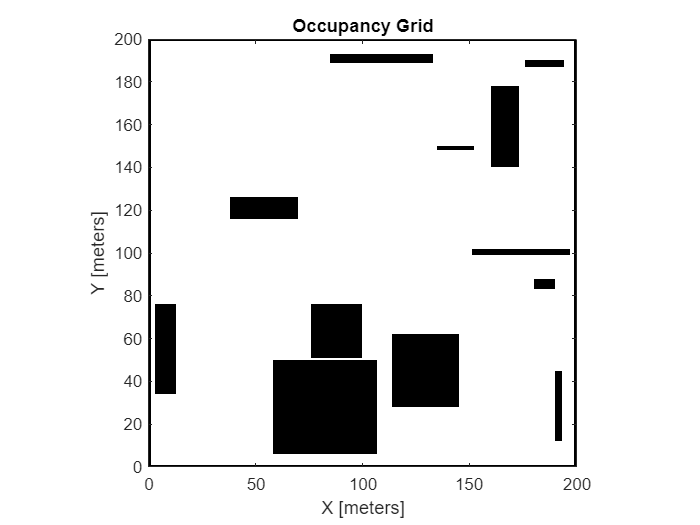

ss = stateSpaceSE2;
sv = validatorOccupancyMap(ss);

load occupancy_map.mat
Map = occupancyMap(omap);
show(Map)


sv.Map = Map

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: Inf


sv.ValidationDistance = 0.01

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: 0.0100


ss.StateBounds = [Map.XWorldLimits;Map.YWorldLimits;[-pi pi]];


planner = plannerRRT(ss,sv,MaxConnectionDistance=10);


start = [40 70 0];
goal = [180 30 0];

rng(100, 'twister');
[pathObj, solvInf] = plan(planner, start, goal)

pathObj =   navPath with properties:

      StateSpace: [1×1 stateSpaceSE2]
          States: [21×3 double]
       NumStates: 21
    MaxNumStates: Inf


solvInf = struct with fields:
      IsPathFound: 1
         ExitFlag: 1
         NumNodes: 91
    NumIterations: 111
         TreeData: [275×3 double]


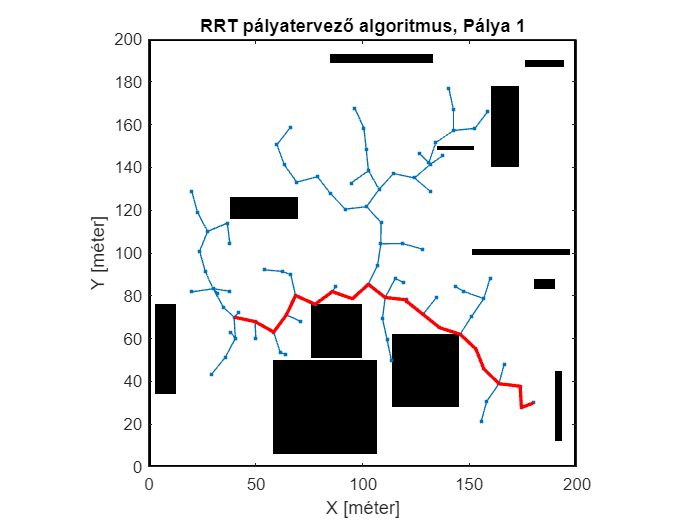



show(Map)
hold on
% Tree expansion
plot(solvInf.TreeData(:,1),solvInf.TreeData(:,2),'.-')
% Draw path
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2)
title("RRT pályatervező algoritmus, Pálya 1")
xlabel("X [méter]")
ylabel("Y [méter]")

pathObj.States(:,1)

ans =    40.0000
   49.7893
   58.5054
   64.4578
   68.7245
   77.8418
   85.9104
   95.3469
  102.7198
  110.5845


pathObj.States(:,2)

ans =    70.0000
   67.9581
   63.0564
   71.0917
   80.1357
   76.0279
   81.9353
   78.6260
   85.3818
   79.2060
